# photometric attitude estimation using UKF (quaternion)

UKFでlight curve attitude estimation

## state variables


$${\bf x}=[{\bf q}^T, {\bf \omega}^T]^T$$


`q`: quaternion where q(4) is the scalar part 

`w`: angular rate, rad/s

## note

NA

## references 

NA

## revisions

20220805 y.yoshimura, minor changes

20210209  y.yoshimura, y.yoshimula@gmail.com

See also orbitConst, mainATOM.

clc
clear
cls

## constants

earthVSOP = vsopConst; % VSOP parameters
const = orbitConst; % constants for orbital motion

## simulation conditions

% true value calculated by mainAttiOrbit.mlx
fName = "flatPlate";
load(strcat(fName,'.mat'));

% random number generator
rng(2022,'twister');

## observations and noise

tn_ = length(t_);

sigMapp = 0.1;
mAppNoise = mApp + sigMapp .* randn(tn_, 1);

% observations
dTmp = vecnorm(obsRel, 2, 2); % m, distance between sat and observer
mAppInv = magInv(mAppNoise(:,1), dTmp); % true obs. (relative magnitude inverse)

## UKF paras.

n_ = 3; % # of state variable := [error GRP and angular rate]


### UKF parameters

ukfPara.alpha = 0.0001;
ukfPara.beta = 2;
ukfPara.kappa = 0;
ukfPara.lambda = 0;
ukfPara = setUKFpara(n_, ukfPara.alpha, ukfPara.beta, ukfPara.kappa, ukfPara.lambda)

ukfPara = フィールドをもつ struct :
     alpha: 1.0000e-04
      beta: 2
     kappa: 0
    lambda: 0
       w0m: 0
       wim: 0.1667
       w0c: 3.0000
       wic: 0.1667



% estimated observation noise (standard deviation)
sigEst = 3 * sigMapp;
Rest = sigEst.^2;
Qest = 0 * deg2rad(1e-2)^2 .* eye(3); % process noise


### pre-allocation

xEst = zeros(tn_, n_); % [euler angles, angular rates]
p = zeros(tn_, n_); % diagonal components of covariance matrix (Pcov)
qGlobal = zeros(tn_, 4);
ye0 = 0;
yez = zeros(2*n_,1);
yeOut = zeros(tn_, 1);


## initial estiamte and covariance

qGlobal(1,:) = q(1,:);  % true initial
tmp = zyx2q(4, deg2rad(-20), ...
    deg2rad(50), ...
    deg2rad(30)); % initial estimate error of quaternion
qGlobal(1,:) = qMult(4, 1, tmp, q(1,:));


#### initial covariance for 3$\sigma
$bound 

iniErr = deg2rad(100);
p(1,:) = (iniErr * 3)^2 .* ones(1,3);
Pcov = diag(p(1,:));

% x:= error GRP
xEst(1,:) = zeros(1,n_);

### Gneralized Rodrigues parameters

aGRP = 1;
fGRP = 2 * (aGRP + 1);

## UKF


for i = 1:tn_-1
    dt_ = t_(i+1) - t_(i);    

    [xEst(i+1,:), qGlobal(i+1,:), Pcov] = lcUKF(jdHistory(i+1), dt_, xEst(i,:), Pcov, mAppNoise(i+1), ...
        ukfPara, Qest, Rest, fGRP, aGRP, qGlobal(i,:), w(i,:), r(i+1,:), obsECI(i+1,:), sat, const, earthVSOP);

end

no observation update
no observation update
no observation update
no observation update
no observation update
no observation update
no observation update
no observation update
no observation update


## data handling

qe = qErr(4, q, qGlobal);
zyxE = q2zyx(4, qe);
phiE = zyxE(:,1);
thetaE = zyxE(:,2);
psiE = zyxE(:,3);


## show figures

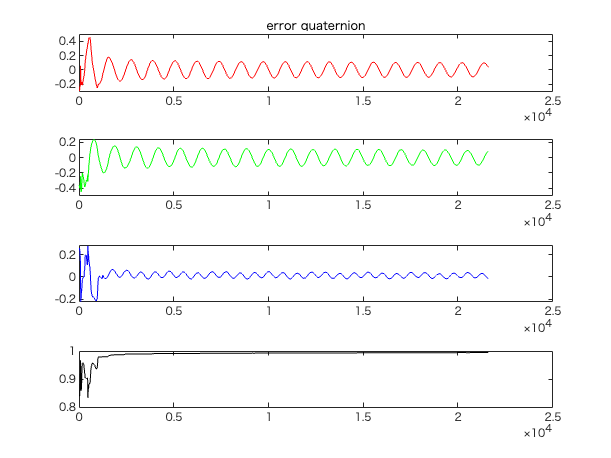

figure
tiledlayout(4,1),nexttile
plot(t_, qe(:,1), 'r')
title('error quaternion')
nexttile
plot(t_, qe(:,2), 'g')
nexttile
plot(t_, qe(:,3), 'b')
nexttile
plot(t_, qe(:,4), 'k')

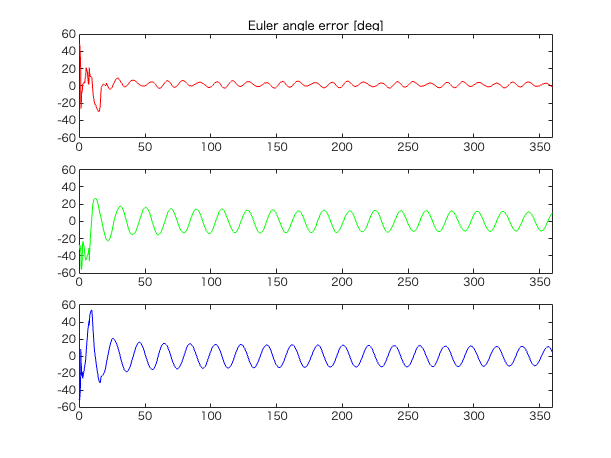


figure
tiledlayout(3,1),nexttile
plot(t_/60, rad2deg(phiE), 'r')
title('Euler angle error [deg]')
xlim([0 60*6]),ylim([-60 60])
nexttile
plot(t_/60, rad2deg(thetaE), 'g')
xlim([0 60*6]),ylim([-60 60])
nexttile
plot(t_/60, rad2deg(psiE), 'b')
xlim([0 60*6]),ylim([-60 60])